% Model_Plant_4_100
% Define parameters
k = 1.5614;    % Value of 'k'
tau = 3293.2;    % Value of 'tau'

% Define control input function (example: step function)
u = @(t) 1 * (t >= 1);  % Step function at t = 1

% Define the differential equation function
f1 = @(t, x, xr) -1/tau *(x-xr) + k/tau * u(t);

% Initial condition
xr = 100;   % Reference value
x0 = 210;   % Initial value of x

% Time span
tspan = 0:15:3600;

% Solve the differential equation
[~, x1] = ode45(@(t,x) f1(t, x, xr), tspan, x0);

% MRAC Control
% Define system parameters
k = 1.5614;    % Value of 'k'
tau = 3293.2;    % Value of 'tau'

% Parameters
am = 0.0015; % Reference model parameter
bm = 0.001;   % Reference model parameter
a = 1/tau;   % Plant parameter
b = k/tau;   % Plant parameter
gamma = 1e-08; % Adaptation rate

% Control gains
kx = (am - a)/b

kx = 2.5232

kr = bm/b

kr = 2.1091

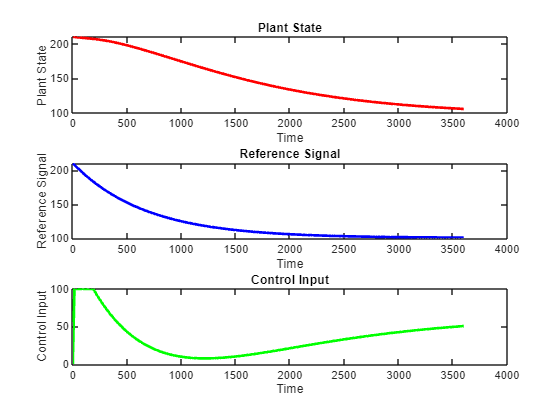


% Simulation parameters
dt = 15; % Time step
t_end = 3600; % Simulation time

% Reference signal
t = 0:dt:t_end;

% Define the differential equation function for reference model
x_hat = 210;
f = @(t, xm, xr) -am * (xm - xr) + bm;

% Solve the differential equation for reference model
[~, xm] = ode45(@(t,x) f(t, x, xr), t, x_hat);
r = xm;

% Initialize variables
x = zeros(size(t));  % Plant state
x(1) = x0; % initial condition

theta = zeros(size(t));  % Parameter estimate
theta(1) = 3.9; % initial guess
u = zeros(size(t));  % Control input
error = zeros(size(t));  % Vector to store error

% Main loop
for j = 2:length(t)
     % Error
     e = r(j) - x(j-1);
     error(j) = e;
            
    % Control law
    u(j) = kx * x(j-1) + kr * r(j) - theta(j-1) * x(j-1);
        
    % Limit control input to the range [0, 100]
    u(j) = min(max(u(j), 0), 100);
            
    % Update plant state
    x(j) = x(j-1) + dt * (-a * x(j-1) + b * u(j));
            
    % Adaptation law (MIT Rule)
    theta_dot = -gamma * e * x(j-1);
    theta(j) = theta(j-1) + dt * theta_dot;
 end
    
% Plot results
figure;
subplot(3,1,1);
plot(t, x, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Plant State');
title('Plant State');

subplot(3,1,2);
plot(t, r, 'b', 'LineWidth', 2);
xlabel('Time');
ylabel('Reference Signal');
title('Reference Signal');

subplot(3,1,3);
plot(t, u, 'g', 'LineWidth', 2);
xlabel('Time');
ylabel('Control Input');
title('Control Input');

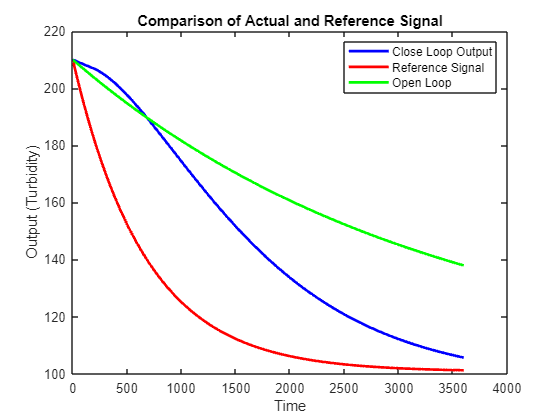


% Plot comparison of actual and reference signal
figure;
plot(t, x, 'b', t, r, 'r','LineWidth', 2);
hold on
plot(t, x1, 'g', 'LineWidth', 2)
hold off
xlabel('Time');
ylabel('Output (Turbidity)');
legend('Close Loop Output', 'Reference Signal', 'Open Loop');
title('Comparison of Actual and Reference Signal');

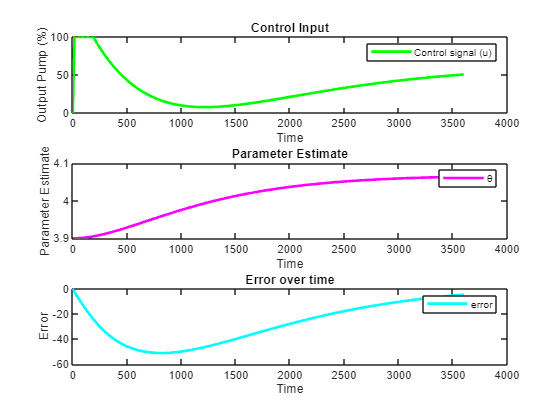


subplot(3,1,1)
plot(t,u, 'g', 'LineWidth', 2);
xlabel('Time');
legend('Control signal (u)')
ylabel('Output Pump (%)');
title('Control Input');

subplot(3,1,2)
plot(t, theta, 'm', 'LineWidth', 2);
xlabel('Time');
legend('θ')
ylabel('Parameter Estimate');
title('Parameter Estimate');

subplot(3,1,3)
plot(t, error, 'c', 'LineWidth', 2);
xlabel('Time');
legend('error')
ylabel('Error');
title('Error over time');

% % Model_Plant_4_100
% % Define parameters
% k = 1.5614;    % Value of 'a'
% tau = 3293.2;    % Value of 'b'
% 
% % Define control input function (example: step function)
% u = @(t) 1 * (t >= 1);  % Step function at t = 1
% 
% % Define the differential equation function
% f1 = @(t, x, xr) -1/tau *(x-xr) + k/tau * u(t);
% 
% % Initial condition
% xr = 100;   % Reference value
% x0 = 210;   % Initial value of x
% 
% % Time span
% tspan = 0:15:10000;
% 
% % Solve the differential equation
% [~, x1] = ode45(@(t,x) f1(t, x, xr), tspan, x0);
% 
% % MRAC Control
% % Define system parameters
% k = 1.5614;    % Value of 'k'
% tau = 3293.2;    % Value of 't1'
% 
% % Parameters
% am = 0.0015; % Reference model parameter
% bm = 0.001;   % Reference model parameter
% a = 1/tau;   % Plant parameter
% b = k/tau;   % Plant parameter
% 
% % Simulation parameters
% dt = 15; % Time step
% t_end = 10000; % Simulation time
% 
% % Reference signal
% t = 0:dt:t_end;
% 
% % Define the differential equation function for reference model
% x_hat = 210;
% f = @(t, xm, xr) -am * (xm - xr) + bm;
% 
% % Solve the differential equation for reference model
% [~, xm] = ode45(@(t,x) f(t, x, xr), t, x_hat);
% r = xm';
% 
% % Initialize variables
% x = zeros(size(t));  % Plant state
% x(1) = x0; % initial condition
% 
% theta = ones(size(t));  % Parameter estimate
% u = zeros(size(t));  % Control input
% num_gamma = 50; % Number of gamma values to test
% gamma_values = linspace(1e-10, 0.1, num_gamma); % Range of gamma values
% error = zeros(length(t), num_gamma);  % Matrix to store error for each gamma
% % Initialize performance matrix
% performance_matrix = zeros(1, num_gamma);
% 
% % Search gamma
% for i = 1:num_gamma
%     gamma = gamma_values(i);
%     % Main loop
%     for j = 2:length(t)
%         % Error
%         e = r(j) - x(j-1);
%         error(j, i) = e; % Store error in corresponding column
% 
%         % Control law
%         u(j) = kx * x(j-1) + kr * r(j) - theta(j-1) * x(j-1);
% 
%         % Limit control input to the range [0, 100]
%         u(j) = min(max(u(j), 0), 100);
% 
%         % Update plant state
%         x(j) = x(j-1) + dt * (-a * x(j-1) + b * u(j));
% 
%         % Adaptation law (MIT Rule)
%         theta_dot = -gamma * e * x(j-1);
%         theta(j) = theta(j-1) + dt * theta_dot;
%     end
%     % Calculate Integral of Absolute Error (IAE) for the current gamma
%     performance_matrix(i) = sum(abs(error(:, i))) * dt;
% end